clear;clc;close all;fclose('all');

params

BW = 250000;
Fc = 250000;
Interp = 5;

% CIC Params
M = 1; % Differential delay
N = 2; % Number of stages

Read Signal from SW

file = fopen('../Xilinx/SW_Source/ofdm/files/TxIfftSamples1.txt','r');
nfft = fscanf(file,"%d,",1);
ofdm_symbols = fscanf(file,"%d,",1);
cp_len = fscanf(file,"%d,",1);
ofdm_signal = fscanf(file,"%lf, %lf\n",[2,(nfft+cp_len)*ofdm_symbols]);
ofdm_signal = complex(ofdm_signal(1,:),ofdm_signal(2,:));

Plot baseband spectrum:

Ts = 1/BW;
t = 0:Ts:((nfft+cp_len)*ofdm_symbols)*Ts-Ts; % Time vector at baseband
nfft_plot = nfft*4; % Nfft for plotting spectrum
F = (-nfft_plot/2:nfft_plot/2-1)/nfft_plot*BW;

Interpolate with MATLAB function

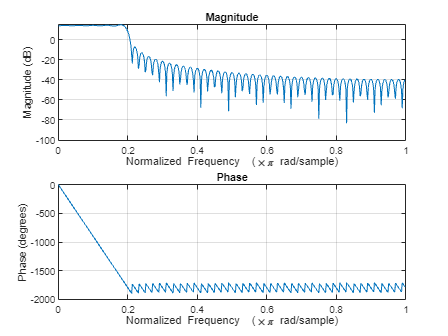

Fs_up = BW*Interp;
Ts_up = 1/Fs_up;
t_up = 0:Ts_up:((nfft+cp_len)*ofdm_symbols)*Ts_up-Ts_up;
F_up = (-nfft_plot/2:nfft_plot/2-1)/nfft_plot*Fs_up;

[Interp_sig_mat,taps] = interp(ofdm_signal,Interp,10,1);
freqz(taps,1)

Interpolate with CIC 

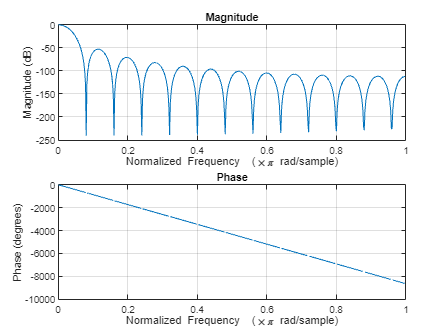

Rd = Interp^N;
h = ones(Rd,1);
for i = 1:N 
    h = conv(h,h);
end
h = h / sum(h);
% Interpolate the signal
up_cic_sig = zeros(Interp*length(ofdm_signal),1);
up_cic_sig(1:Interp:end) = ofdm_signal;
Interp_cic_sig = filter(h,1,up_cic_sig);
freqz(h,1)

Plot Interpolated spectrum:

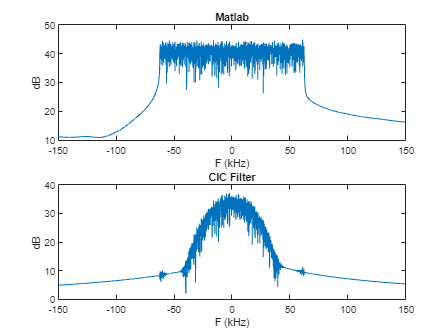

x_lim = [-150 150];
figure(),subplot(2,1,1),plot(F_up/1000,10*log10(abs(fftshift(fft(Interp_sig_mat,nfft_plot))))),xlabel('F (kHz)'),ylabel('dB'),title('Matlab'),xlim(x_lim)
subplot(2,1,2),plot(F_up/1000,10*log10(abs(fftshift(fft(Interp_cic_sig,nfft_plot))))),xlabel('F (kHz)'),ylabel('dB'),title('CIC Filter'),xlim(x_lim)